Rozważmy transmitancję:


$$G(s) = \frac{0.01 * (s^2 + \frac{1}{10}s+4)}{s(9s^5 + \frac{23}{10}s^4 + \frac{101}{10}s^3 + \frac{7}{10}s^2 + 1)}$$


Ploty Nyquista oraz Bodego są dla tej transmitancji dość skomplikowane (wiele zapętleń, dopełnienie w nieskończoności, szeroki zakres amplitud nie ułatwia sprawy) i ciężko jest szybko wyznaczyć zapas fazy i amplitudy.

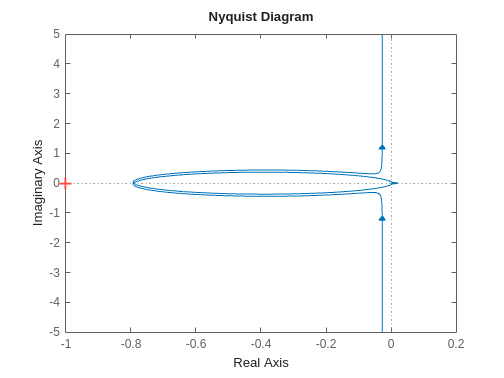

G = tf(0.01*[1 0.1 4], [9, 23/10, 101/10, 7/10, 1, 0]);

figure;
grid on;
hold on;
nyquist(G);

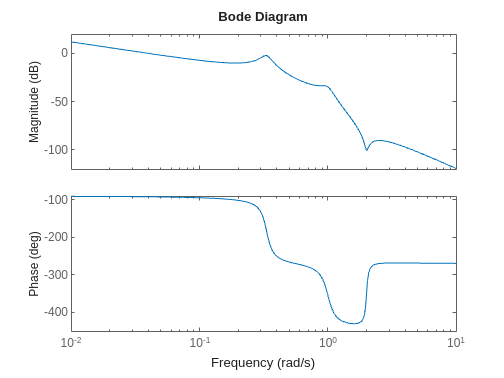

figure;
grid on;
hold on;
bode(G);

Jeśli natomiast wyrysujemy plot Nicholsa, to wyznaczenie tego zapasu jest niemal natychmiastowe:

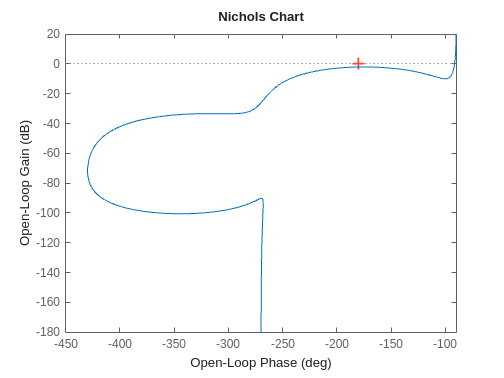

figure;
grid on;
hold on;
nichols(G);